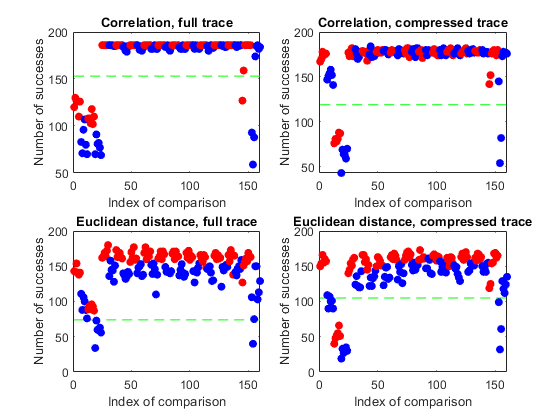

for measureChosen = 1 : 4
    if (measureChosen < 3)
        indSelected = (measureChosen-1)*4 +1;
    else
        indSelected = (measureChosen-3)*4 +6;
    end
    subplot(2,2,measureChosen)
    plot(1:length(successMat),repmat(selectedPoints(indSelected,2),1,length(successMat)),'--g')
    hold on
    ylabel('Number of successes')
    xlabel('Index of comparison')
    if (measureChosen == 1)
        title("Correlation, full trace")
    elseif (measureChosen == 2)
        title("Correlation, compressed trace")
    elseif (measureChosen == 3)
        title("Euclidean distance, full trace")
    else
        title("Euclidean distance, compressed trace")
    end
    for i = 1 : length(successMat)
        if (successMat(2,i,measureChosen) == 1)
            scatter(i,successMat(1,i,measureChosen),'red','filled')
        else
            scatter(i,successMat(1,i,measureChosen),'blue','filled')
        end
    end
    hold off
end